# Decision Trees

`We try a different approach here by removing date_account_created_day_number, date_account_created_month_number and date_account_created_year to check how these features affect our model.`

## Part 1: without PCA

## Part 1.1: training-testing splitting

`Remove the above fields from the training set`

trainingSetDT = trainingSet(:,1:12);
testingSetDT  = testingSet(:,1:12);

`Apply Decision Tree on the 2 training sets`

`1) Original Training and Testing Sets`

tree = fitctree(trainingSet, trainingSetTarget);
[labelDT, scoreDT] = predict(tree, testingSet);

`Calculating Accuracy`

disp('Accuracy of the Decision Tree model is')

Accuracy of the Decision Tree model is


accuracy = sum(labelDT==testingSetTarget)/size(labelDT,1)

accuracy = 0.5346

`Calculating NDCG score`

[DCG_DT_1, NDCG_DT_1] = dcgScore(testingSetTarget, scoreDT, 5);
disp('NDCG score of the Decision Tree model is')

NDCG score of the Decision Tree model is


NDCG_DT_1

NDCG_DT_1 = 0.6712

`2) Modified Training and Testing Sets`

tree_1 = fitctree(trainingSetDT, trainingSetTarget);
[labelDT_1, scoreDT_1] = predict(tree_1, testingSetDT);

`Calculating Accuracy`

disp('Accuracy of the Decision Tree model on modified data is')

Accuracy of the Decision Tree model on modified data is


accuracy = sum(labelDT_1==testingSetTarget)/size(labelDT_1,1)

accuracy = 0.5385

`Calculating NDCG score`

[DCG_DT_2, NDCG_DT_2] = dcgScore(testingSetTarget, scoreDT_1, 5);
disp('NDCG score of the Decision Tree model with modified data is')

NDCG score of the Decision Tree model with modified data is


NDCG_DT_2

NDCG_DT_2 = 0.6735

## Part 1.2: cross valdiation

`1) Original Training and Testing Sets`

`Decision Tree using Cross-validation 10 folds`

Mdl_cvDT = fitctree([trainingSet;testingSet], [trainingSetTarget;testingSetTarget], 'CrossVal','on');
disp('Accuracy of the cross validated model is')

`Calculating Accuracy`

% CVMdl = crossval(Mdl_cvDT);
disp('Accuracy of the cross-validated model is');
accuracy = 1-kfoldLoss(Mdl_cvDT)
[labelDT_CV, scoreDT_CV] = kfoldPredict(Mdl_cvDT);

`Calculating NDCG score`

[DCG_DTcv, NDCG_DTcv] = dcgScore([trainingSetTarget;testingSetTarget], scoreDT_CV, 5);
disp('NDCG score of Decision Tree model using cross validated data is')
NDCG_DTcv

`2) Modified Training and Testing Sets`

`Decision Tree using Cross-validation 10 folds`

Mdl_cvDT_2 = fitctree([trainingSetDT;testingSetDT], [trainingSetTarget;testingSetTarget], 'CrossVal','on');
disp('Accuracy of the cross validated model is')

`Calculating Accuracy`

% CVMdl = crossval(Mdl_cvDT);
disp('Accuracy of the cross-validated model is');
accuracy = 1-kfoldLoss(Mdl_cvDT_2)
[labelDT_CV_2, scoreDT_CV_2] = kfoldPredict(Mdl_cvDT_2);

`Calculating NDCG score`

[DCG_DTcv_2, NDCG_DTcv_2] = dcgScore([trainingSetTarget;testingSetTarget], scoreDT_CV_2, 5);
disp('NDCG score of Decision Tree model using cross validated data is')
NDCG_DTcv_2

## Selecting Tree Parameters:

`Split parameter:`

`(entropy)`

tree_ent = fitctree(trainingSetDT, trainingSetTarget,'SplitCriterion','deviance');
[labelDT_ent, scoreDT_ent] = predict(tree_ent, testingSetDT);

`Calculating Accuracy`

disp('Accuracy of the Decision Tree model on modified data is')
accuracy = sum(labelDT_ent==testingSetTarget)/size(labelDT_ent,1)

`Calculating NDCG score`

[DCG_DT_ent, NDCG_DT_ent] = dcgScore(testingSetTarget, scoreDT_ent, 5);
disp('NDCG score of the Decision Tree model with modified data is')
NDCG_DT_ent

`(twoing)`

tree_twoing = fitctree(trainingSetDT, trainingSetTarget,'SplitCriterion','twoing');
[labelDT_twoing, scoreDT_twoing] = predict(tree_twoing, testingSetDT);

`Calculating Accuracy`

disp('Accuracy of the Decision Tree model on modified data is')
accuracy = sum(labelDT_twoing==testingSetTarget)/size(labelDT_twoing,1)

`Calculating NDCG score`

[DCG_DT_twoing, NDCG_DT_twoing] = dcgScore(testingSetTarget, scoreDT_twoing, 5);
disp('NDCG score of the Decision Tree model with modified data is')
NDCG_DT_twoing

`max Spliting`

maxSplit = 30;
accuracy = zeros(1,maxSplit);
% DCG_DT_twoing = zeros(size(testingSetDT,1),length(unique(testingSetTarget)),10);
NDCG_DT_twoing = accuracy;
for node = 1:maxSplit
    tree_twoing = fitctree(trainingSetDT, trainingSetTarget,'SplitCriterion','twoing','MaxNumSplits',node);
    [labelDT_twoing, scoreDT_twoing] = predict(tree_twoing, testingSetDT);
    accuracy(node) = sum(labelDT_twoing==testingSetTarget)/size(labelDT_twoing,1);
    [~, NDCG_DT_twoing(node)] = dcgScore(testingSetTarget, scoreDT_twoing, 5);
end

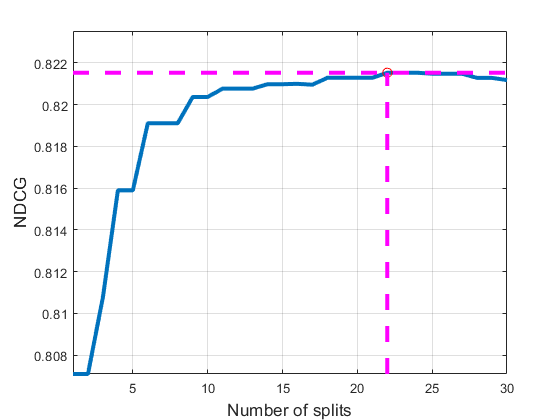

figure;
plot(NDCG_DT_twoing,'LineWidth',3);
xlabel('Number of splits','FontSize',13);
ylabel('NDCG','FontSize',13);
[maxNDCG,maxNDCGI]=max(NDCG_DT_twoing);
hold on;
plot(maxNDCGI,maxNDCG,'o','MarkerSize',7,'Color',[1,0,0]);
plot(1:maxSplit,ones(1,maxSplit)*maxNDCG,'--','LineWidth',3,'Color',[1,0,1]);
plot([maxNDCGI,maxNDCGI],[min(NDCG_DT_twoing),maxNDCG],'--','LineWidth',3,'Color',[1,0,1]);
xlim([1,maxSplit]);
ylim([min(NDCG_DT_twoing),maxNDCG+0.002]);
grid on;

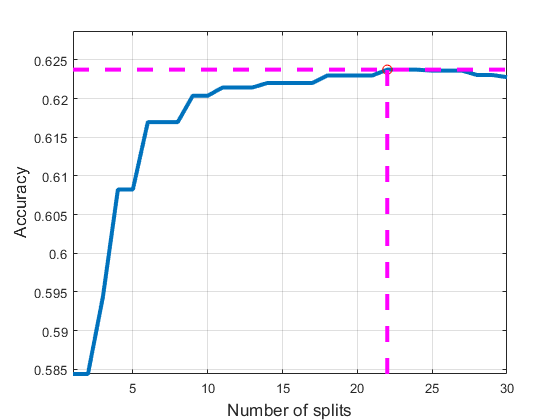

figure;
plot(accuracy,'LineWidth',3);
xlabel('Number of splits','FontSize',13);
ylabel('Accuracy','FontSize',13);
[maxacc,maxaccI]=max(accuracy);
hold on;
plot(maxaccI,maxacc,'o','MarkerSize',7,'Color',[1,0,0]);
plot(1:maxSplit,ones(1,maxSplit)*maxacc,'--','LineWidth',3,'Color',[1,0,1]);
plot([maxaccI,maxaccI],[min(accuracy),maxacc],'--','LineWidth',3,'Color',[1,0,1]);
xlim([1,maxSplit]);
ylim([min(accuracy),maxacc+0.005]);
grid on;

`max leaves:`

maxLeaves = 50;
intervals = 1;
accuracy = zeros(1,maxLeaves);
% DCG_DT_twoing = zeros(size(testingSetDT,1),length(unique(testingSetTarget)),10);
NDCG_DT_twoing = accuracy;
for leaf = 1:maxLeaves
    tree_twoing = fitctree(trainingSetDT, trainingSetTarget,'SplitCriterion','twoing','MaxNumSplits',1,'MinLeafSize',leaf);
    [labelDT_twoing_leaves, scoreDT_twoing_leaves] = predict(tree_twoing, testingSetDT);
    accuracy(leaf) = sum(labelDT_twoing_leaves==testingSetTarget)/size(labelDT_twoing_leaves,1);
    [~, NDCG_DT_twoing(leaf)] = dcgScore(testingSetTarget, scoreDT_twoing_leaves, 5);
end

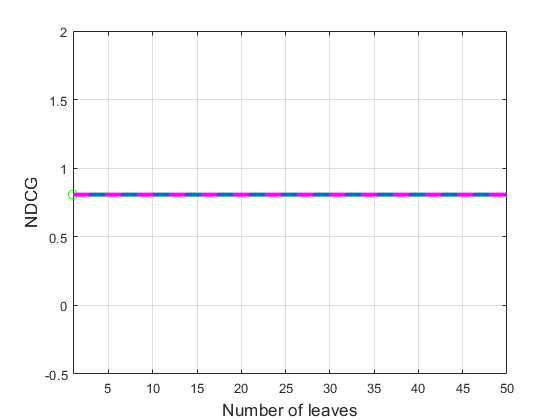

figure;
plot(NDCG_DT_twoing,'LineWidth',3);
xlabel('Number of leaves','FontSize',13);
ylabel('NDCG','FontSize',13);
[maxNDCG,maxNDCGI]=max(NDCG_DT_twoing);
hold on;
plot(maxNDCGI,maxNDCG,'o','MarkerSize',7,'Color',[0,1,0]);
plot(1:maxLeaves,ones(1,maxLeaves)*maxNDCG,'--','LineWidth',3,'Color',[1,0,1]);
plot([maxNDCGI,maxNDCGI],[min(NDCG_DT_twoing),maxNDCG],'--','LineWidth',3,'Color',[1,0,1]);
xlim([1,maxLeaves]);
%ylim([min(NDCG_DT_twoing),maxNDCG+0.002]);
grid on;

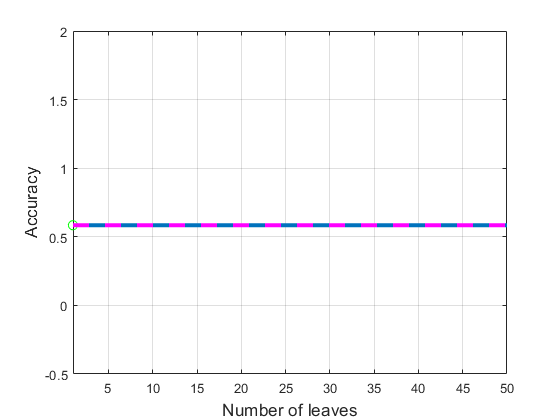

figure;
plot(accuracy,'LineWidth',3);
xlabel('Number of leaves','FontSize',13);
ylabel('Accuracy','FontSize',13);
[maxacc,maxaccI]=max(accuracy);
hold on;
plot(maxaccI,maxacc,'o','MarkerSize',7,'Color',[0,1,0]);
plot(1:maxLeaves,ones(1,maxLeaves)*maxacc,'--','LineWidth',3,'Color',[1,0,1]);
plot([maxaccI,maxaccI],[min(accuracy),maxacc],'--','LineWidth',3,'Color',[1,0,1]);
xlim([1,maxLeaves]);
%ylim([min(accuracy),maxacc+0.005]);
grid on;

## Part2: With PCA

tree_PCA = fitctree(trainingSetPCA, trainingSetTargetPCA,'SplitCriterion','twoing','MaxNumSplits',22);
[labelPCA, scorePCA] = predict(tree_PCA, testingSetPCA);

`Calculating Accuracy`

disp('Accuracy of the Decision Tree model on modified data is')

Accuracy of the Decision Tree model on modified data is


accuracy = sum(labelPCA==testingSetTargetPCA)/size(labelPCA,1)

accuracy = 0.5841

`Calculating NDCG score`

[DCG_PCA, NDCG_PCA] = dcgScore(testingSetTargetPCA, scorePCA, 5);
disp('NDCG score of the Decision Tree model with modified data is')

NDCG score of the Decision Tree model with modified data is


NDCG_PCA

NDCG_PCA = 0.8066